% 3D Lidar point cloud
veloReader = velodyneFileReader("lidar\300\2022-12-10-16-53-10_Velodyne-VLP-16-Data.pcap","VLP16");
lidar_pc = readFrame(veloReader);

% Stereo camera point cloud
camera_pc = pcread("ZED\vga\point_cloud_PLY_3029_376_06-12-2022-19-40-31.ply");

savePointCloud(lidar_pc.Location, 'lidar_pts.mat');
savePointCloud(camera_pc.Location, 'camera_pts.mat');

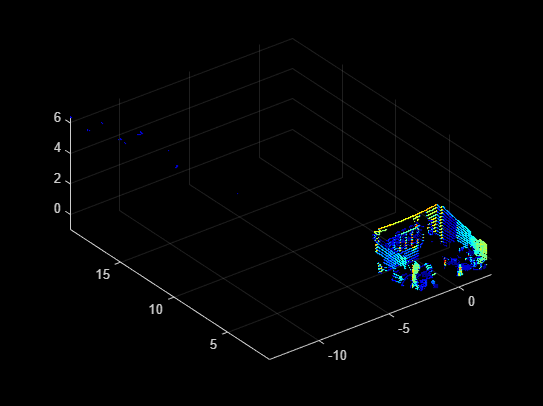

pcshow(lidar_pc);

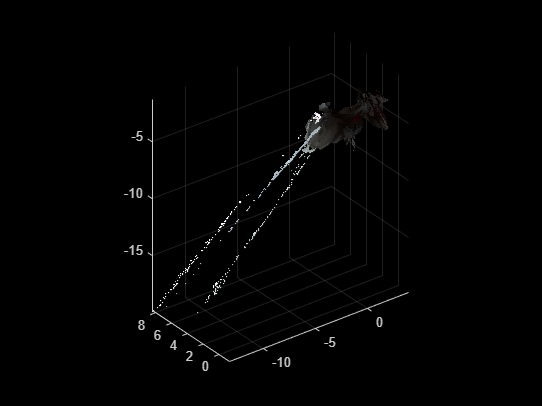

pcshow(camera_pc);

% Visualize Lidar point cloud
figure;
scatter3(lidar_pts(:,1), lidar_pts(:,2), lidar_pts(:,3));

Unrecognized function or variable 'lidar_pts'.

title('Lidar Point Cloud');
xlabel('X');
ylabel('Y');
zlabel('Z');

% Visualize camera point cloud
figure;
scatter3(camera_pts(:,1), camera_pts(:,2), camera_pts(:,3));
title('Camera Point Cloud');
xlabel('X');
ylabel('Y');
zlabel('Z');

## Function Definitions

function plyToMat(plyFile, matFile)
    % plyToMat converts a PLY file to a MAT file
    % 
    % Inputs:
    %   plyFile: Name of PLY file to convert (including file path and extension)
    %   matFile: Name of resulting MAT file (including file path and extension)
    
    % Read PLY file
    [pts, faces] = plyread(plyFile);
    
    % Convert faces to face vertex indices
    faces = faces.vertex_indices;
    
    % Save points and faces to MAT file
    save(matFile, 'pts', 'faces');
end

function savePointCloud(pts, fileName)
    % savePointCloud saves a point cloud as an Nx3 matrix
    % 
    % Inputs:
    %   pts: Point cloud data (Nx3 matrix)
    %   fileName: Name of resulting file (including file path and extension)
    
    % Save point cloud to file
    save(fileName, 'pts');
end